xlin = 0 : 1 : 95;
ylin = 0 : 1 : 125;
[xm, ym] = meshgrid(xlin, ylin);
pr1 = inppdata("0602a.txt");
pr2 = inppdata("0602b.txt");

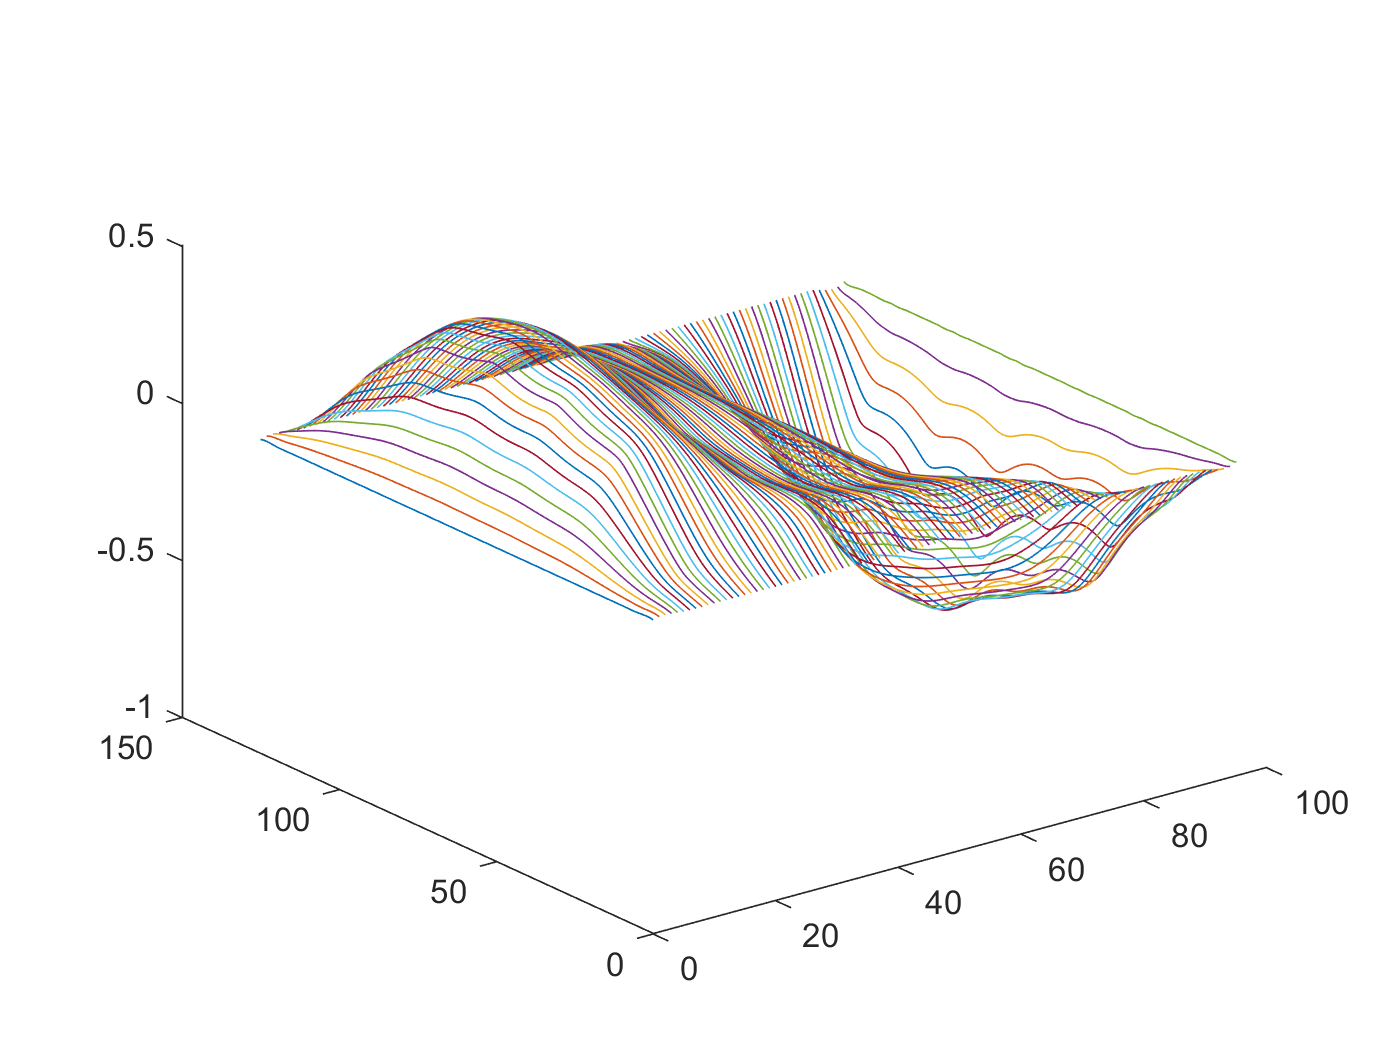

pp1 = cumtrapz(pr1(xm, ym));
pp2 = cumtrapz(pr2(xm, ym)')';
pend = (pp1 + pp2 ) ./ 2;
plot3(xm, ym, pr1(xm, ym));

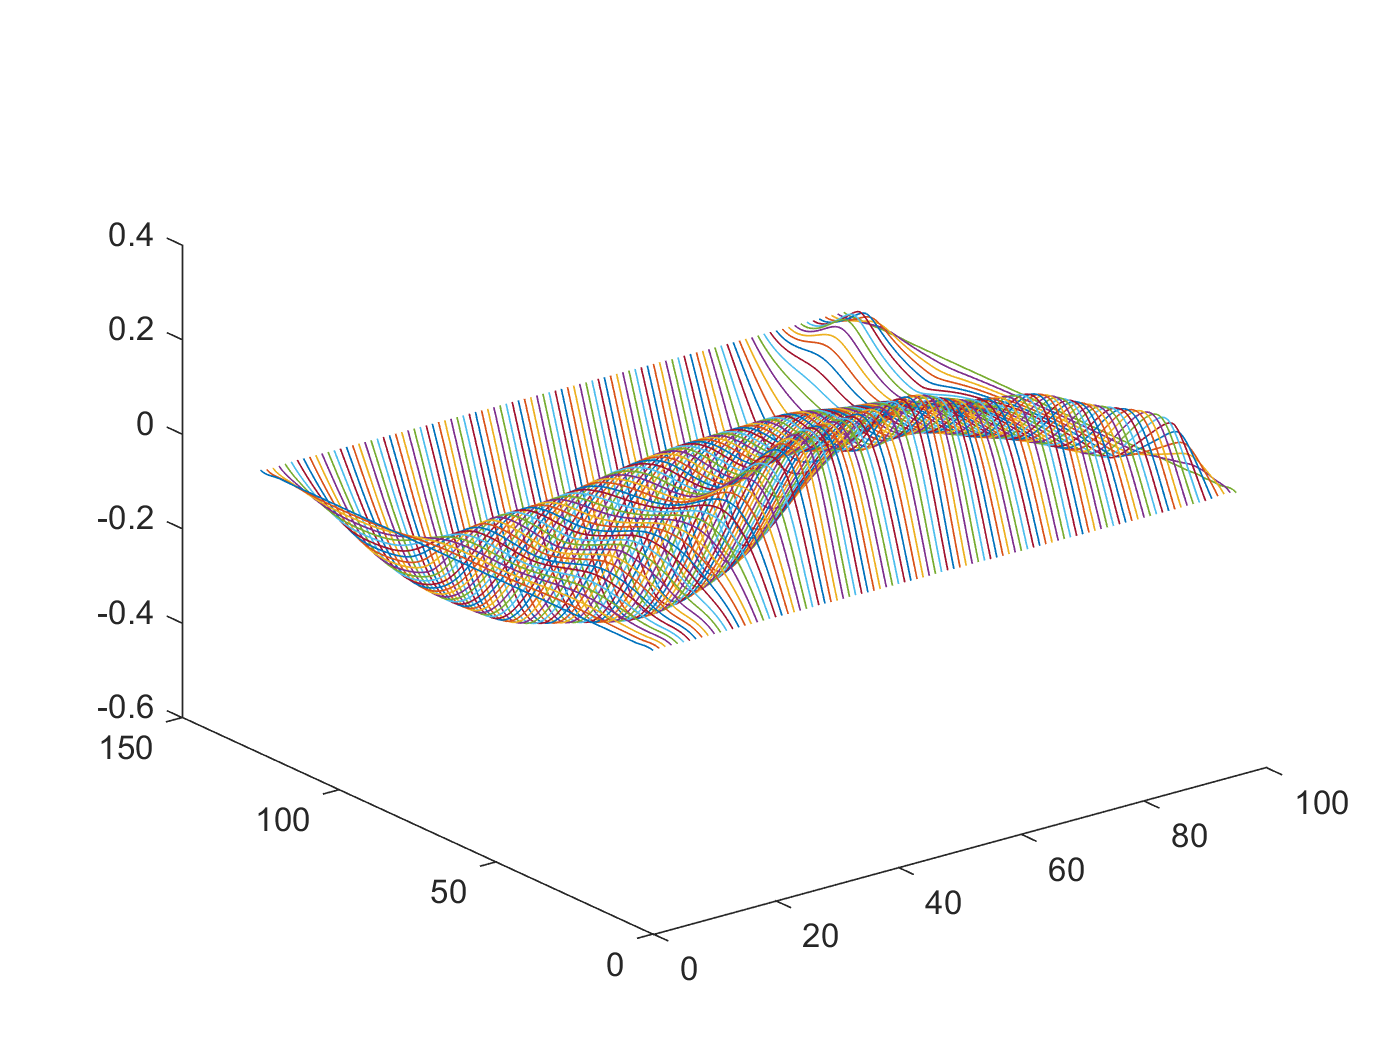

plot3(xm, ym, pr2(xm, ym));

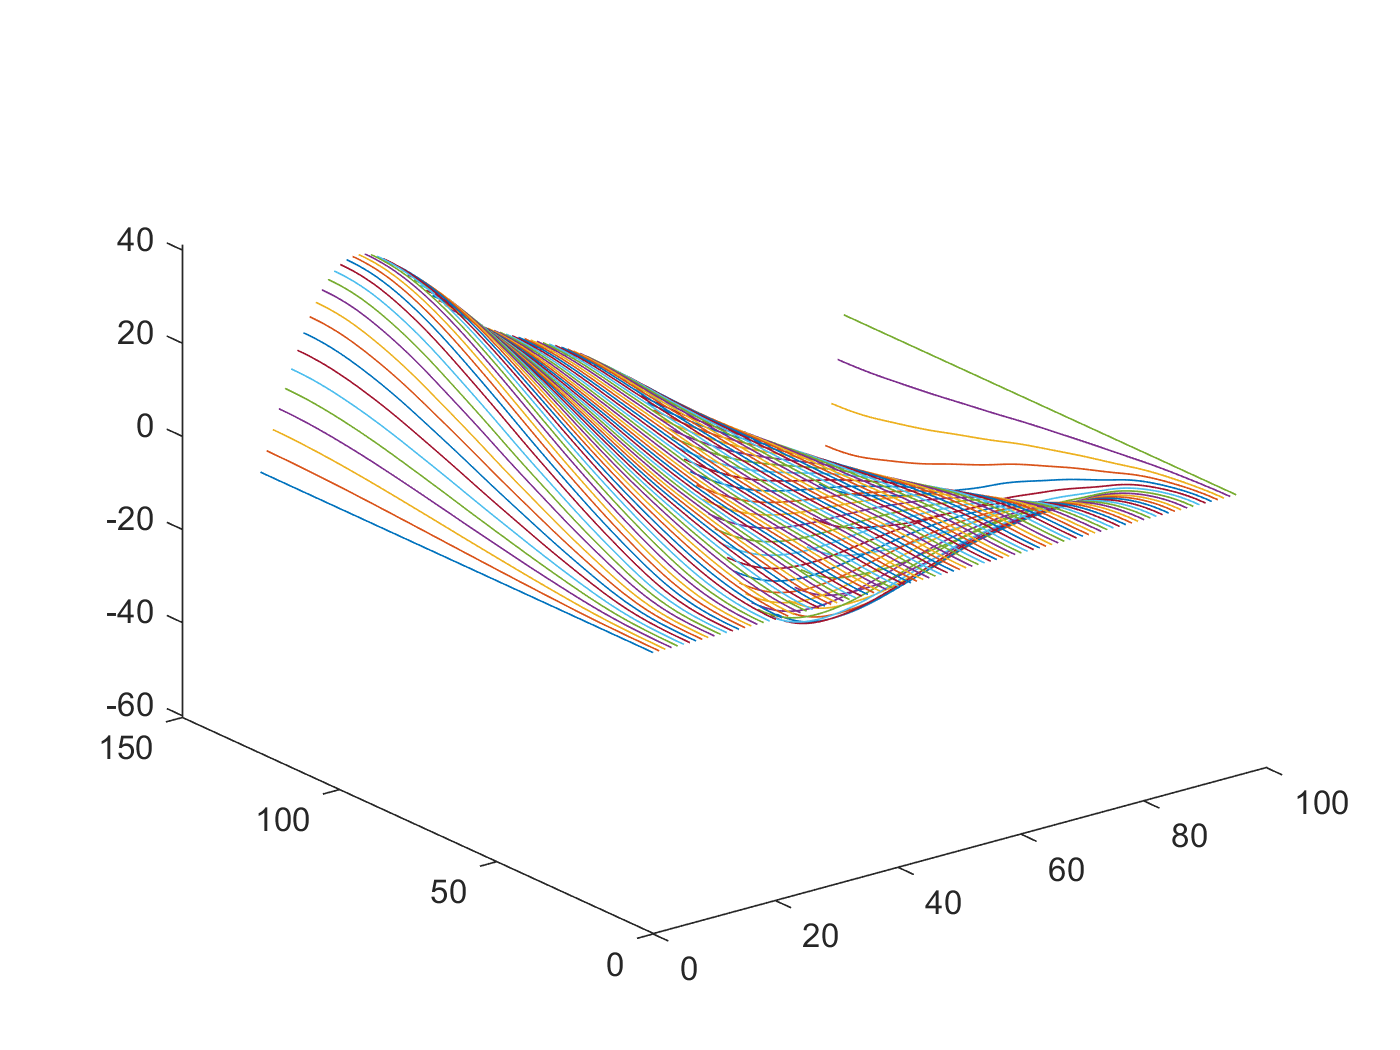

plot3(xm, ym, pp1);

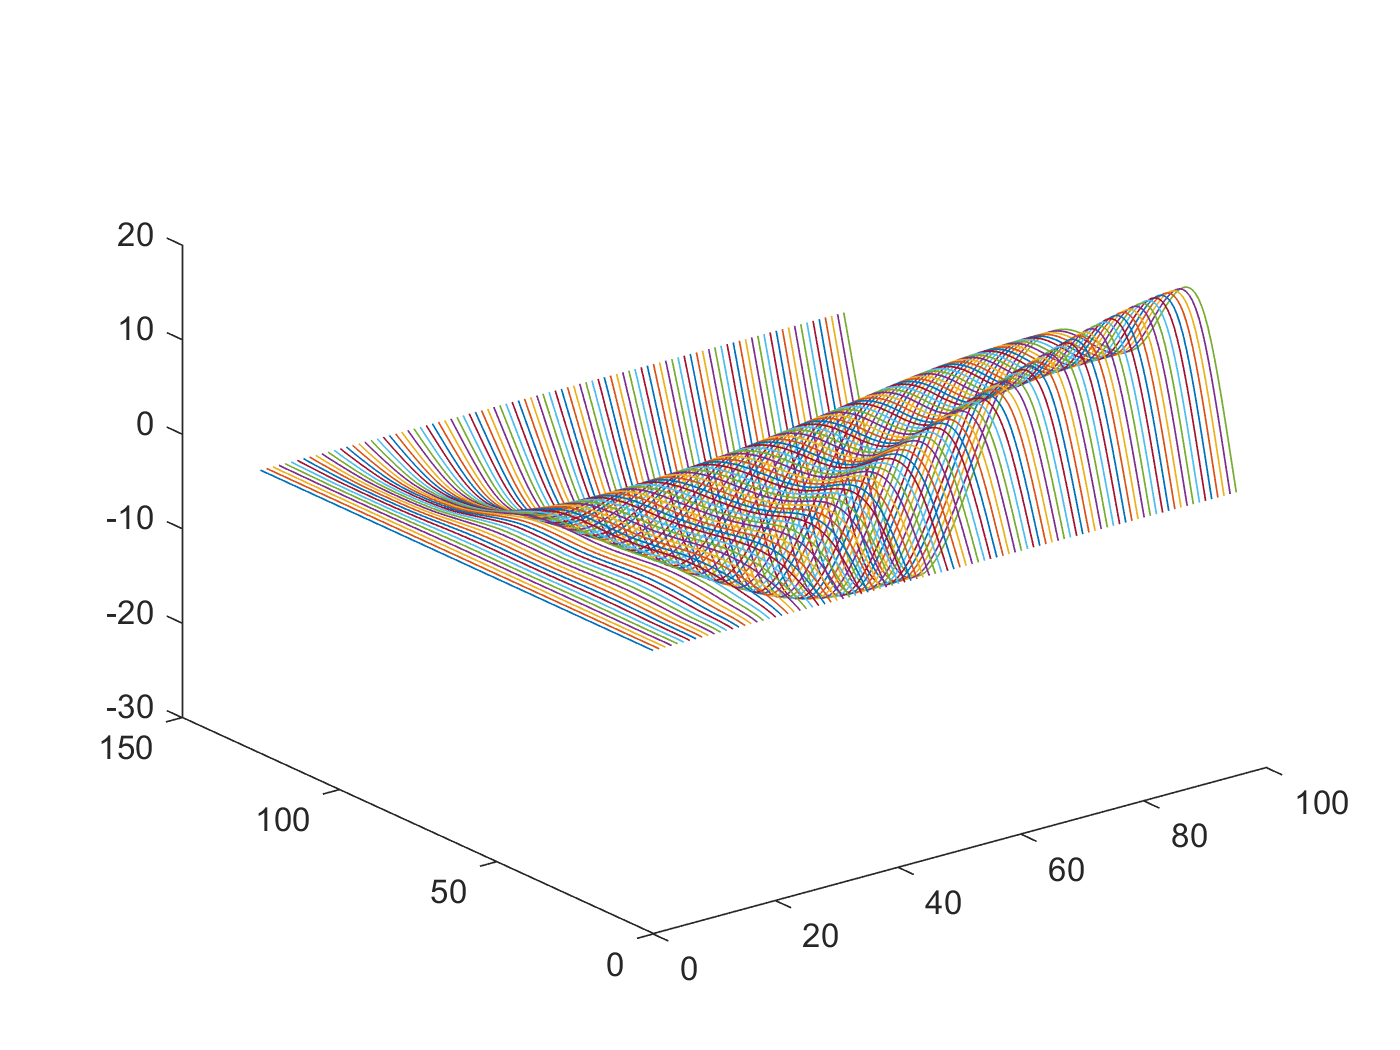

plot3(xm, ym, pp2);

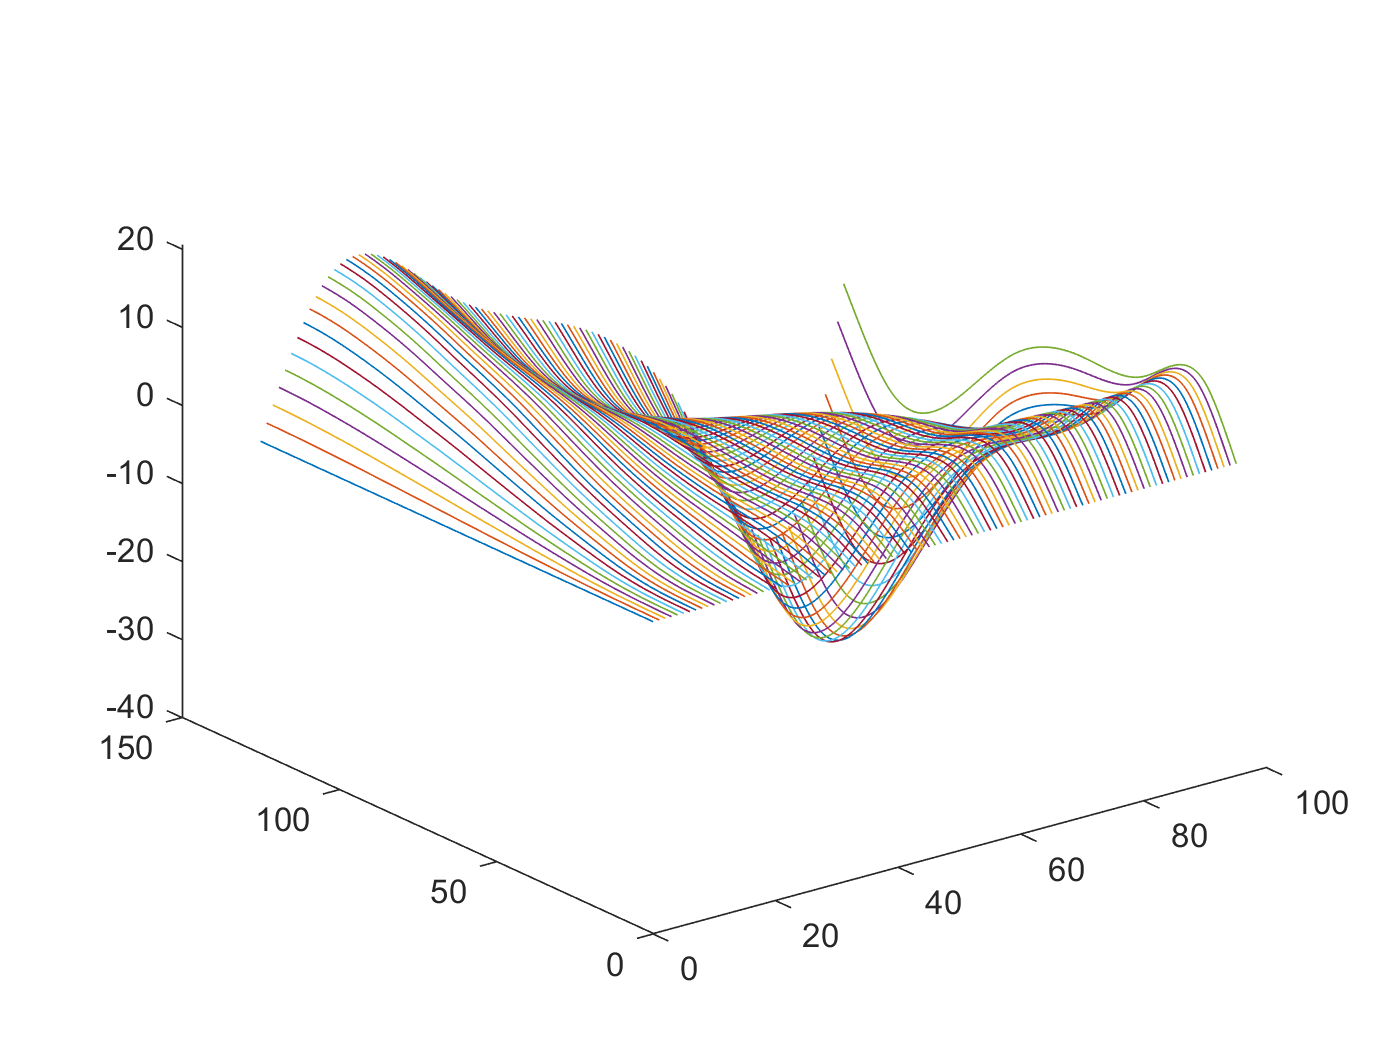

plot3(xm, ym, pend);

function surface = inppdata(filename)
    preData = importdata(filename);
    rawData.x = preData(1:end, 1);
    rawData.x = rawData.x(~ isnan(rawData.x));
    rawData.y = preData(1:end, 2);
    rawData.y = rawData.y(~ isnan(rawData.y));
    rawData.z = preData(1:end, 3);
    rawData.z = rawData.z(~ isnan(rawData.z));
    [rawData.xF, rawData.zF, rawData.yF] = prepareSurfaceData(rawData.x, rawData.z, rawData.y);
    ft = 'biharmonicinterp';
    surface = fit( [rawData.xF, rawData.yF], rawData.zF, ft, 'Normalize', 'on' );
end